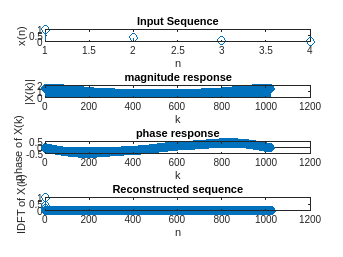

%clc;clear;close all;
x=input('enter the input sequence x(n)');

N=input('enter the size of DFT : ');
X=fft(x,N);
Xa=abs(X);
Xp=angle(X);
k=0:N-1;
figure(1);
subplot(411),stem(x),xlabel('n'),ylabel('x(n)'),title('Input Sequence');
subplot(412),stem(k,Xa),xlabel('k'),ylabel('|X(k)|'),title('magnitude response');
subplot(413),stem(k,Xp),xlabel('k'),ylabel('phase of X(k)'),title('phase response');
x_cap=ifft(X); %idft of the signal
subplot(414),stem(abs(x_cap)),xlabel('n'),ylabel('IDFT of X(k)'),title('Reconstructed sequence');
